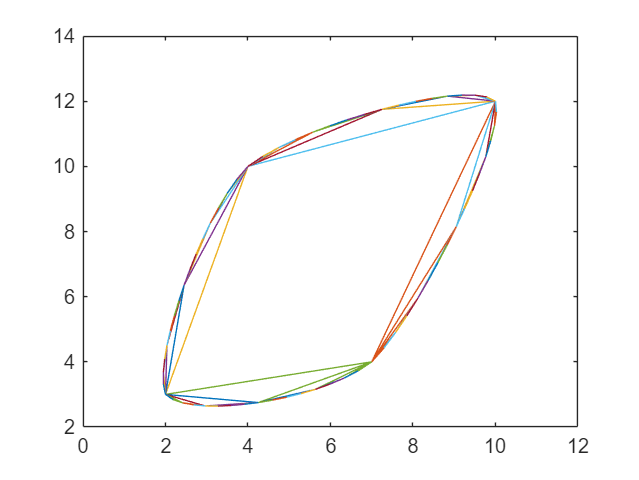

clc
clear
close
function y=gen(p1,p2,p3,p4,alpha)
    y=(p2+p3)/2+((p2+p3)/2-(p1+p4)/2)*alpha;
end
n=5;
x=[2,4,10,7];
y=[3,10,12,4];
num=length(x);
alpha=1/10;
arrayX=cell(1,n);
arrayY=cell(1,n);
arrayX{1}=x;
arrayY{1}=y;
for i=2:n
    arrayX{i}=[arrayX{i},arrayX{i-1}(1)];
    arrayX{i}=[arrayX{i},gen(arrayX{i-1}(num*power(2,i-2)),arrayX{i-1}(1),arrayX{i-1}(2),arrayX{i-1}(3),alpha)];
    for j=2:num*power(2,i-2)-2
        arrayX{i}=[arrayX{i},arrayX{i-1}(j)];
        arrayX{i}=[arrayX{i},gen(arrayX{i-1}(j-1),arrayX{i-1}(j),arrayX{i-1}(j+1),arrayX{i-1}(j+2),alpha)];
    end
    j=j+1;
    arrayX{i}=[arrayX{i},arrayX{i-1}(j)];
    arrayX{i}=[arrayX{i},gen(arrayX{i-1}(j-1),arrayX{i-1}(j),arrayX{i-1}(j+1),arrayX{i-1}(1),alpha)];
    j=j+1;
    arrayX{i}=[arrayX{i},arrayX{i-1}(j)];
    arrayX{i}=[arrayX{i},gen(arrayX{i-1}(j-1),arrayX{i-1}(j),arrayX{1}(1),arrayX{i-1}(2),alpha)];
end
for i=2:n
    arrayY{i}=[arrayY{i},arrayY{i-1}(1)];
    arrayY{i}=[arrayY{i},gen(arrayY{i-1}(num*power(2,i-2)),arrayY{i-1}(1),arrayY{i-1}(2),arrayY{i-1}(3),alpha)];
    for j=2:num*power(2,i-2)-2
        arrayY{i}=[arrayY{i},arrayY{i-1}(j)];
        arrayY{i}=[arrayY{i},gen(arrayY{i-1}(j-1),arrayY{i-1}(j),arrayY{i-1}(j+1),arrayY{i-1}(j+2),alpha)];
    end
    j=j+1;
    arrayY{i}=[arrayY{i},arrayY{i-1}(j)];
    arrayY{i}=[arrayY{i},gen(arrayY{i-1}(j-1),arrayY{i-1}(j),arrayY{i-1}(j+1),arrayY{i-1}(1),alpha)];
    j=j+1;
    arrayY{i}=[arrayY{i},arrayY{i-1}(j)];
    arrayY{i}=[arrayY{i},gen(arrayY{i-1}(j-1),arrayY{i-1}(j),arrayY{1}(1),arrayY{i-1}(2),alpha)];
end
for i=1:n
    for j=1:num*power(2,i-1)-1
        plot(arrayX{i}(j),arrayY{i}(j),arrayX{i}(j+1),arrayY{i}(j+1));
        line([arrayX{i}(j),arrayX{i}(j+1)],[arrayY{i}(j),arrayY{i}(j+1)]);
        hold on;
    end
    plot(arrayX{i}(j+1),arrayY{i}(j+1),arrayX{i}(1),arrayY{i}(1));
    line([arrayX{i}(j+1),arrayX{i}(1)],[arrayY{i}(j+1),arrayY{i}(1)]);
    hold on;
end